clc
close all
clearvars

% Folder in which all test data folders are located
rcbench_folder = 'C:\Users\Tomaso\Desktop\Thesis\main\RC Testbench Data\RC Testbench Data';

% List of folders of the specific tests
test_folder = {...'T-motor F80 Pro 1900 kv - GemFan 6030 4R(green) - 4S'
              ...'T-motor F80 Pro 1900 kv - Qprop 5x4x3 (pink) - 4S'
              ...'T-motor F80 Pro 1900 kv 7x4R (orange) - 4S'
              ...'T-motor MN3515 400 kv - APC 13x10EP - 6S - Pusher'
              ...'T-motor MN3515 400 kv - APC 14x8.5EP - 6S - Pusher'
              ...'T-motor MN3515 400 kv - APC 16x10EP - 6S - Pusher'
              ...'T-motor MN3510 360 kv - APC 11x5.5 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 12x6 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 12x12 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 11x5.5 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 12x6 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 12x12 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 13x10 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 13x10 EP - 6S - Pusher'
              ...'T-motor MN3510 360 kv - APC 14x8.5 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 16x10 EP - 6S'
              ...'T-motor MN3510 360 kv - MF1302R - 4S'
              ...'T-motor MN3510 360 kv - MF1302R - 4S - Pusher'
              'T-motor MN3510 360 kv - MF1302R - 6S'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - Pusher'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - pusher - esc settings'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - Pusher - ESC 48 khz'
              ...'T-motor MN3510 360 kv - MF1302R FW folding hub - 6S - Pusher'
              };

%% Get the data
for n = 1:length(test_folder)
    folder = fullfile(rcbench_folder, test_folder{n});
    data{n} = RCTestbench.getData(folder);
%     data{n} = data{n}.getFOM;
end

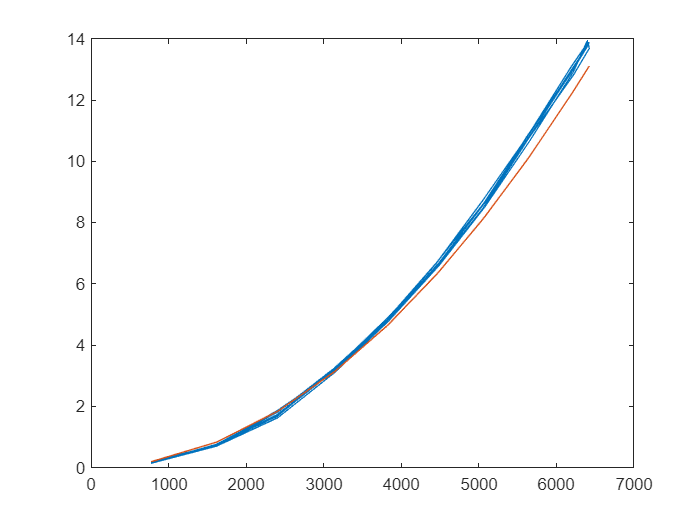

pwm = [data{1,1}.perf.test1.pwm;data{1,1}.perf.test2.pwm;data{1,1}.perf.test3.pwm];
T =  [data{1,1}.perf.test1.T;data{1,1}.perf.test2.T;data{1,1}.perf.test3.T];
Qm =  [data{1,1}.perf.test1.Qm;data{1,1}.perf.test2.Qm;data{1,1}.perf.test3.Qm];
rpm = [data{1,1}.perf.test1.RPM;data{1,1}.perf.test2.RPM;data{1,1}.perf.test3.RPM];


d = 339.8e-3;
pitch = 121.6;
r = d/2;
bp = 1/3*r;
rpm0 = min(rpm);
rpm2rads= 2*pi/60;
w0 = rpm0 * rpm2rads;
%rpm_q = linspace(rpm0,10000,100);
% w = rpm_q * rpm2rads;
% Vt = (w-w0)*bp;
Vt_q = linspace(0,30,5);
w = Vt_q./bp+w0;
rpm_min = w./rpm2rads;
%query_mat = zeros(size(rpm,1),size(Vt_q,2));
[X,Y]=meshgrid(rpm_min,rpm);
query_mat=Y>X;
rcCL = mean(T./(rpm.*rpm2rads).^2 .* (3/r^3));
figure(1)
clf
plot(rpm,T)
hold on
plot(rpm,rcCL*r*(1/3*r^2*(rpm.*rpm2rads).^2))

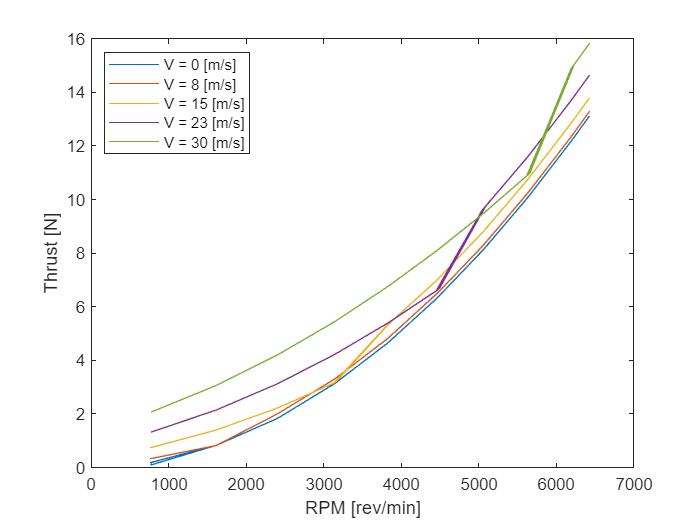





%T_as = (T + rcCL * r * Vt_q.^2).*query_mat+ 0.5*rcCL*r*(1/3*r^2*(rpm.*rpm2rads).^2+r*(rpm.*rpm2rads)*Vt_q+Vt_q.^2).*(1-query_mat);
T_as = rcCL * r *(1/3*r^2*(rpm.*rpm2rads).^2+Vt_q.^2).*query_mat+ 0.5*rcCL*r*(1/3*r^2*(rpm.*rpm2rads).^2+r*(rpm.*rpm2rads)*Vt_q+Vt_q.^2).*(1-query_mat);

rpm_q = linspace(rpm0,max(rpm),100);
%[~,rpm_q]=meshgrid(rpm_min,rpm_q);

figure(3)
clf
%plot(rpm,T);
% hold on
% for i = 1:size(Vt_q,2)
%     p = polyfit(Y(:,i),T_as(:,i),2);
%     f = polyval(p,Y(:,i));
%     plot(Y(:,i),f)
% end
plot(rpm,T_as.')
% lsline
legendStrings = "V = " + string(round(Vt_q))+" [m/s]";
legend(legendStrings,'Location','northwest')
xlabel('RPM [rev/min]')
ylabel('Thrust [N]')

% figure(1)
% plot(rpm_q,Vt)
% figure(2)
% plot(rpm,T)
